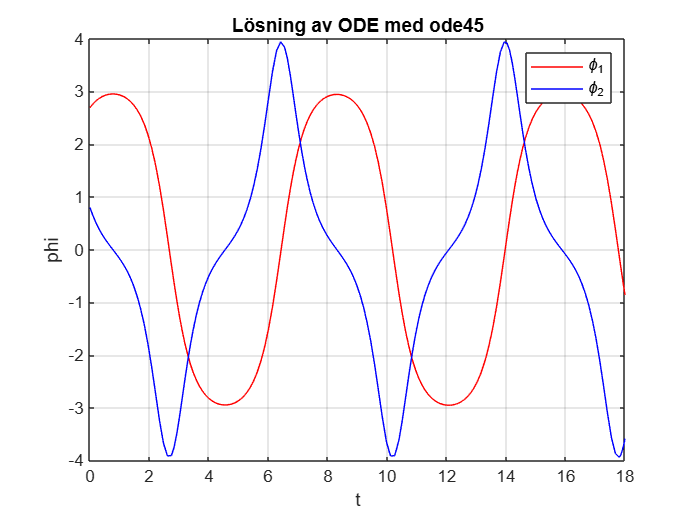

clear all, close all, clf

%parametrar
g=9.82;
L=2.5;
phi1=6*pi/7;%randvillkor 1
phi2=0.8;
function tetaprim = func(t,x)
tetaprim(1)=x(2);
tetaprim(2)=-((9.82)/(2.5))*sin(x(1));
tetaprim=tetaprim';
end
[t,x]= ode45(@func,[0,18],[phi1;phi2]);
%phi1 är vinkel, phi2är vinkelhast
plot(t, x(:,1), 'r', t, x(:,2), 'b');
xlabel('t');
ylabel('\phi');
legend('\phi_1', '\phi_2');
title('Lösning av ODE med ode45');
grid on;


%beräkning av nollställen
bp = [];
rad = 1;
for i = 2:length(x(:,2))
    a = x(i,2)*x(i-1,2);
    if a < 0
        bp(rad,:) = [i-1,i];%vilka index där tecken byts
        rad = rad+1;
    end
end

%P_t = @(Q) x(11,1) + ((x(12,1)-x(11,1)) / ((t(12)-t(11)))*(Q-t(11))) + (Q-t(11))*(Q-t(12))*((x(12,2)-((x(12,1)-x(11,1))/((t(12)-t(11)))*(Q-t(11))))*(Q-t(11))+ (x(11,2)-((x(12,1)-x(11,1)) / ((t(12)-t(11)))*(Q-t(11))))*(Q-t(12)))/(t(12)-t(11))^2;
%Punkter för interpolation
t1_val=[t(bp(1,2)+1),t(bp(1,2)),t(bp(1,1))];
t2_val=[t(bp(3,2)+1),t(bp(3,2)),t(bp(3,1))];
phi11_val=[x(bp(1,2)+1,2),x(bp(1,2),2),x(bp(1,1),2)];
phi12_val=[x(bp(3,2)+1,2),x(bp(3,2),2),x(bp(3,1),2)];
%Interpolationsfunktioner
phi1_interpol1 = @(q) interp1(t1_val,phi11_val,q,"pchip");
phi1_interpol2 = @(q) interp1(t2_val,phi12_val,q,"pchip");
t1=fzero(phi1_interpol1,0.7);
t2=fzero(phi1_interpol2,10);
delta_t=t2-t1;
fprintf('Periodtid=%.4f\n',delta_t);

Periodtid=7.5347


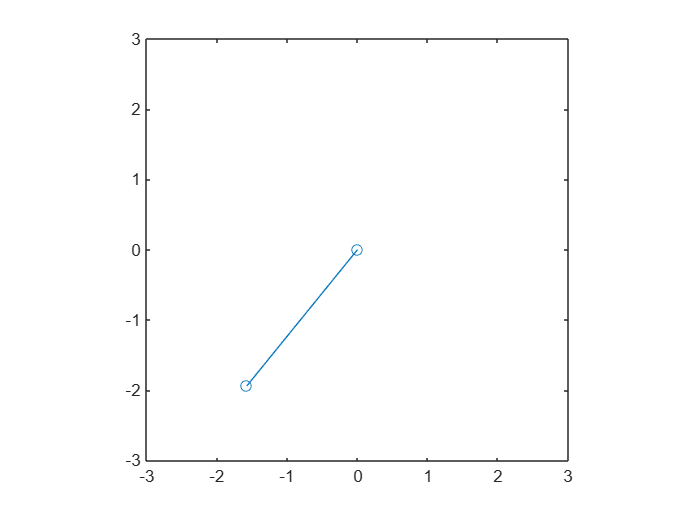

%t1= interp1(t(9:14),x(9:14,2),-2:3,'linear');
%P1=@(t) interp1(t(9:14),x(9:14,2),0,'spline');

k_value1 = (x(bp(1,2),2) - x(bp(1,1),2)) / (t(bp(1,2)) - t(bp(1,1)));
function anim(t,x,L)
    for i=1:length(t)-1
        x0=L*sin(x(i));y0=-L*cos(x(i));
        plot([0,x0],[0,y0],'-o')
        axis('equal')
        axis([-1 1 -1 0]*1.2*L)
        ylim([-3,3]);
        drawnow
        pause(t(i+1)-t(i))
    end
end

anim(t,x(:,1),L)